# Quantization


$$\{q,p\}=1 \rightarrow -\frac{i}{\hbar}[Q,P]=1$$



$$\frac{df}{dt}= \{f,h\} \rightarrow \frac{d}{dt}O(t)=-\frac{i}{\hbar}[O,H]$$


In general,


$$O_{\{f,g\}}=-\frac{i}{\hbar}[O_f,O_g]$$


So, representation is


$$\pi^{'}(f)=-iO_f$$


The Schrödinger representation $\Gamma^{'}_S$ provides a unitary representation not of the Lie algebra of all functions on phase space, but of these polynomials of degree at most one, as follows


$$\Gamma^{'}_S(1)=-i1, \ \ \Gamma^{'}_S(q)=-iQ=-iq, \ \ \Gamma^{'}_S(p)=-iP=-\frac{d}{dq}$$


Moving on to quadratic polynomials, we get


$$\Gamma^{'}_S(\frac{q^2}{2})=-i\frac{Q^2}{2}=-i\frac{q^2}{2}$$



$$\Gamma^{'}_S(\frac{p^2}{2})=-i\frac{P^2}{2}=\frac{i}{2}\frac{d^2}{dq^2}$$



$$\Gamma^{'}_S(pq)=-\frac{i}{2}(PQ+QP)$$


# Semi-direct Products

An example: the Euclidean group

syms x y z t real
syms c [1 3]
[s, l1, l2, l3]=so3();
R1=simplify(expm(t*l1));
R2=simplify(expm(t*l2));
R3=simplify(expm(t*l3));
a=eye(3);
a1=a(:,1);
a2=a(:,2);
a3=a(:,3);
v=[x;y;z];

  
$$v \rightarrow (a_2,R_2)\cdot v =a_2+R_2 v$$


v2=c2*a2+R2*v;


$$(a_1,R_1)\cdot ((a_2,R_2)\cdot v)=(a_1,R_1)\cdot (a_2+R_2 v)=a_1+R_1 a_2+R_1 R_2 v$$


Note that this is not what one would get if one took the product group law

on $R^3 \times  SO(3)$, since then the action of $(a_1,R_1)(a_2,R_2)$ on $R^3$ would be


$$v \rightarrow a_1+a_2+R_1R_2 v$$


Given groups $G$ (with operation *) and $H$ (with operation ∆), the **direct product** *G* × *H* is defined as follows:

- The underlying set is the Cartesian product, *G* × *H*. That is, the [ordered pairs](https://www.wikiwand.com/en/Ordered_pair) (*g*, *h*), where *g* ∈ *G* and *h* ∈ *H*.

- The [binary operation](https://www.wikiwand.com/en/Binary_operation) on *G* × *H* is defined component-wise:(*g*1, *h*1) · (*g*2, *h*2) = (*g*1 * *g*2, *h*1 ∆ *h*2)

In [abstract algebra](https://www.wikiwand.com/en/Abstract_algebra), a **normal subgroup** (also known as an **invariant subgroup** or **self-conjugate subgroup**)[[1]](https://www.wikiwand.com/en/Normal_subgroup#citenoteFOOTNOTEBradley2010121) is a [subgroup](https://www.wikiwand.com/en/Subgroup) that is invariant under [conjugation](https://www.wikiwand.com/en/Inner_automorphism) by members of the [group](https://www.wikiwand.com/en/Group_(mathematics)) of which it is a part. In other words, a subgroup $N$  of the group $G$  is normal in $G$  if and only if $gng^{-1} \in N$  for all $g \in G$  and $n \in N$. The usual notation for this relation is  $N \triangleleft G$.

**Definition (Euclidean group)**. The Euclidean group $E(d)$ (sometimes written $ISO(d)$ for “inhomogeneous” rotation group) in dimension d is the product of the translation and rotation groups of $R^d$ as a set, with multiplication law

                
$$(a_1,R_1)(a_2,R_2)=(a_1+R_1a_2,R_1,R_2)$$


(where $a_j \in  R^d$, $R_j \in  SO(d)$ and can be denoted by

               
$$R^d >\triangleleft SO(d)$$


E(d) can also be written as a matrix group, taking it to be the subgroup of $GL(d + 1,R)$ of matrices of the form ($R$ is a $d$ by $d$ orthogonal matrix, **a** a d-dimensional column vector)

                            
$$\pmatrix{R & a \cr 0 &1}$$


One gets the multiplication law for $E(d)$ from matrix multiplication since

            
$$\pmatrix{R_1 & a_1 \cr 0 &1} \pmatrix{R_2 & a_2 \cr 0 &1}=\pmatrix{R_1R_2 & a_1+R_1a_2 \cr 0 &1}$$


syms R [3 3]
syms a [3 1]

E=[R a;zeros(1,3) 1]

$$E = \left(\begin{array}{cccc} R_{1,1} & R_{1,2} & R_{1,3} & a_{1}\\ R_{2,1} & R_{2,2} & R_{2,3} & a_{2}\\ R_{3,1} & R_{3,2} & R_{3,3} & a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

In this case a vector is in the following form

syms v [3 1]
v=[v;1]

$$v = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ 1 \end{array}\right)$$

syms a [3 1] 
T=sym(eye(4));
T(1:3,4)=a

$$T = \left(\begin{array}{cccc} 1 & 0 & 0 & a_{1}\\ 0 & 1 & 0 & a_{2}\\ 0 & 0 & 1 & a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

t1=diff(T,a1);
t2=diff(T,a2);
t3=diff(T,a3);


Definition (Semi-direct product Lie algebra). Given Lie algebras $\mathfrak{k}$ and $\mathfrak{n}$, and an action of elements $Y \in \mathfrak{k}$ on $\mathfrak{n}$ by derivations


$$X \in  \mathfrak{n} \to  Y \cdot  X \in  \mathfrak{n}$$


the semi-direct product $\mathfrak{n} >\triangleleft \mathfrak{k}$ is the set of pairs $(X, Y ) \in  \mathfrak{n} \otimes \mathfrak{k}$ with the Lie bracket


$$[(X1, Y1), (X2, Y2)] = ([X1,X2] + Y1 \cdot  X2 - Y2 \cdot  X1, [Y1, Y2])$$


# The Quantum Free Particle

# as a Representation of the

# Euclidean Group

A basis for the Lie algebra of $E(2)$ is given by the functions:

$l=q_1p_2-q_2p_1$,    $p_1$,    $p_2$

on the $d = 2$ phase space $M = R^4$, where $l$ is a basis for the Lie algebra

$\mathfrak{so}(2)$ of rotations, $p_1, p_2$ a basis for the Lie algebra $R^2$ of translations.

The nonzero Lie bracket relations are given by the Poisson brackets

syms p q [1 2]
l=q1*p2-q2*p1

$$l = p_{2}\,q_{1}-p_{1}\,q_{2}$$

poisson(l,p1,2)

$$ans = p_{2}$$

poisson(l,p2,2)

$$ans = -p_{1}$$

There is an isomorphism of this Lie algebra with a matrix Lie algebra of 3 by 3 matrices given by


$$l \leftrightarrow \pmatrix{0 &-1 &0 \cr 1&0&0 \cr 0&0&0}$$
        
$$p_1 \leftrightarrow \pmatrix{0 &0 &1 \cr 0&0&0 \cr 0&0&0}$$
        
$$p_2 \leftrightarrow \pmatrix{0 &0 &0 \cr 0&0&1 \cr 0&0&0}$$


Note that the Euclidean group $E(d)$ is a subgroup of the Jacobi group

$G^J (d)$, the subgroup of elements of the form

            
$$\pmatrix{\pmatrix{\pmatrix{0 \cr c_p},0},\pmatrix{R & 0 \cr 0 & R}}$$
        
$$@ R \in SO(d)$$


The 


$$\pmatrix{\pmatrix{0 \cr c_p},0} \subset H_{2d+1}$$


make up the group $R^d$ of translations in the $q_j$ coordinates, and the


$$k=\pmatrix{R & 0 \cr 0 & R} \subset Sp(2d,R)$$


are symplectic transformations.

The Lie algebra of $E(d)$ will be a sub-Lie algebra of $g^J (d)$, consisting of elements of the form


$$\pmatrix{\pmatrix{\pmatrix{0 \cr c_p},0},\pmatrix{X & 0 \cr 0 & X}}$$


where $X$ is an antisymmetric $d$ by $d$ matrix.

Since we have realized the Lie algebra of $E(2)$ as a sub-Lie algebra of the

Jacobi Lie algebra $g^J (2)$, quantization via the Schrödinger representation $\Gamma^{'}_S$ provides a unitary Lie algebra representation on the state space $\mathcal{H}$ of functions of the position variables $q_1, q_2$. This will be given by the operators


$$\Gamma^{'}_S(p_1)=-iP_1=\frac{\partial}{\partial{q_1}$$
        
$$\Gamma^{'}_S(p_2)=-iP_2=\frac{\partial}{\partial{q_2}$$


and


$$\Gamma^{'}_S(l)=-iL=-i(Q_1P_2-Q_2P_1)=-(q_1\frac{\partial}{\partial{q_2}}-q_2\frac{\partial}{\partial{q_1}})$$


The Hamiltonian operator for the free particle is


$$H=\frac{1}{2m}(P_1^2+P_2^2)=-\frac{1}{2m}(\frac{\partial^2}{\partial {q_1}^2}+\frac{\partial^2}{\partial {q_2}^2})$$


and solutions to the Schr¨odinger equation can be found by solving the eigenvalue equation


$$H\Psi(q_1,q_2)=-\frac{1}{2m}(\frac{\partial^2}{\partial {q_1}^2}+\frac{\partial^2}{\partial {q_2}^2})\Psi(q_1,q_2)=E\Psi(q_1,q_2)$$


The operators $L, P_1, P_2$ commute with H and so provide a representation of the Lie algebra of $E(2)$ on the space of wavefunctions of energy $E$.

So from this we understand that a representation is an action on a space which leaves something invariant. Here since the operators commutes with Hamiltonian if we act on Schrödinger equation with them energy will be invariant, e.g.


$$L(H |\Psi>=E|\Psi>)=LH |\Psi>=LE|\Psi>=HL |\Psi>=EL|\Psi>=H(L |\Psi>)=E(L|\Psi>)$$


So energy is invariant under the action of $E(2)$ on wavefunctions. 

Every such representation will be labeled by E (Energy). So since


$$H|\Psi>=E|\Psi> \rightarrow <p|H|\Psi>=<p|E|\Psi> \rightarrow (\frac{|p|^2}{2m}-E)<p|\Psi>=0 \rightarrow E=\frac{|p|^2}{2m}$$


Energy values define a circle in momentum space


$$p_1^2+p_2^2=2mE$$


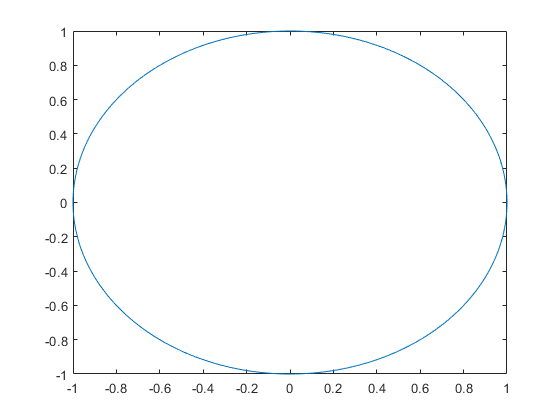

fimplicit(@(x,y) x.^2+y.^2-1)

starting with the action of $E(2)$ on configuration space, and taking the induced action on functions on $R^2$ (the wavefunctions).

$E(2)$ has elements $(a,R)$ with group product (semi-direct product) $(a_1,R_1)(a_2,R_2)=(a_1+R_1 a_2, R_1 R_2)$

Lie algebra of $E(2)$ is


$$l \leftrightarrow \pmatrix{0 &-1 &0 \cr 1&0&0 \cr 0&0&0}$$
        
$$p_1 \leftrightarrow \pmatrix{0 &0 &1 \cr 0&0&0 \cr 0&0&0}$$
        
$$p_2 \leftrightarrow \pmatrix{0 &0 &0 \cr 0&0&1 \cr 0&0&0}$$


l=[0 -1 0;1 0 0;0 0 0]; %rotation so(2)
p1=[0 0 1;0 0 0;0 0 0]; %translations
p2=[0 0 0;0 0 1;0 0 0];
syms a [1 2]
syms t

So group elements are

R=simplify(expm(t*l)) %(0,R)

$$R = \left(\begin{array}{ccc} \cos\left(t\right) & -\sin\left(t\right) & 0\\ \sin\left(t\right) & \cos\left(t\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T=expm(a1*p1+a2*p2) %(a,1)

$$T = \left(\begin{array}{ccc} 1 & 0 & a_{1}\\ 0 & 1 & a_{2}\\ 0 & 0 & 1 \end{array}\right)$$

So, the group action is $(a,R(t))=(a,1)(0,R(t))$

T*R

$$ans = \left(\begin{array}{ccc} \cos\left(t\right) & -\sin\left(t\right) & a_{1}\\ \sin\left(t\right) & \cos\left(t\right) & a_{2}\\ 0 & 0 & 1 \end{array}\right)$$

The group has a unitary representation


$$(a,R(t)) \rightarrow u(a,R(t))$$


on the position space wavefunctions $\psi (q)$, given by the induced action on functions from the action of $E(2)$ on position space $R^2$


$$u(a,R(t))\Psi(q)=\Psi((a,R(t))^{-1} \cdot q)$$


                        
$$=\Psi((-R(-t))a,R(-t))\cdot q)$$
 

                        
$$=\Psi(R(-t)(q-a))$$



$$@ (a,R(t))^{-1}=((a,1)(0,R(t)))^{-1}=(0,R(t))^{-1}(a,1)^{-1}=(0,R(-t))(-a,1)=(-R(-t)a,R(-t))$$


considering the action of translations as the exponential of the Lie algebra representation operators $\Gamma_S^{'}(p_j) = -iP_j$ and the action of rotations as the exponential of the $\Gamma_S^{'}(l) = -iL$


$$u(a, 1)\psi (q) = e^{-i(a_1P_1+a_2P_2)}\psi (q) = \psi (q - a)$$



$$u(0,R(\varphi ))\psi (q) = e^{-i\varphi }L\psi (q) = \psi (R(-\varphi )q)$$


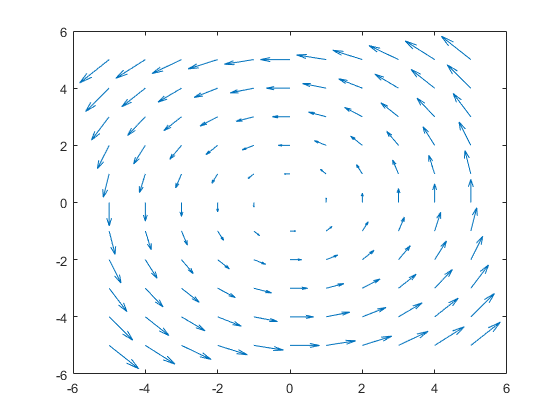

%-q2 1 -p2 11 +q1 2+p1 22

[X Y]=meshgrid(-5:5);
U=-Y;
V=X;
quiver(X,Y,U,V)